files = {
    'prawo_1.wav'
    'prawo_2.wav'
    'prawo_3.wav'
    'lewo_1.wav'
    'lewo_2.wav'
    'lewo_3.wav'
    'stop_1.wav'
    'stop_2.wav'
    'stop_3.wav'
    'start_1.wav'
    'start_2.wav'
    'start_3.wav'
};


labels = [
    1
    1
    1
    2
    2
    2
    3
    3
    3
    4
    4
    4
];

% zakładamy takie samo fs dla wszystkich nagrań
[~, fs] = audioread(files{1});

data = {};

for k=1:length(files)
    data{k} = audioread(files{k});
    data{k} = data{k} / max(data{k});
end

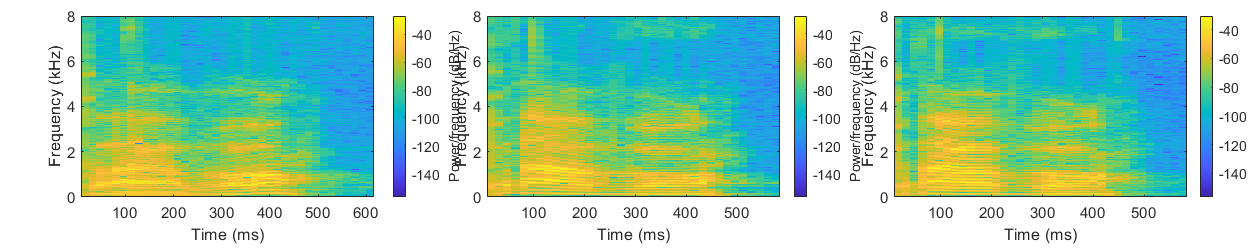

spec3(data{1}, data{2}, data{3}, 512, 256, [], fs);

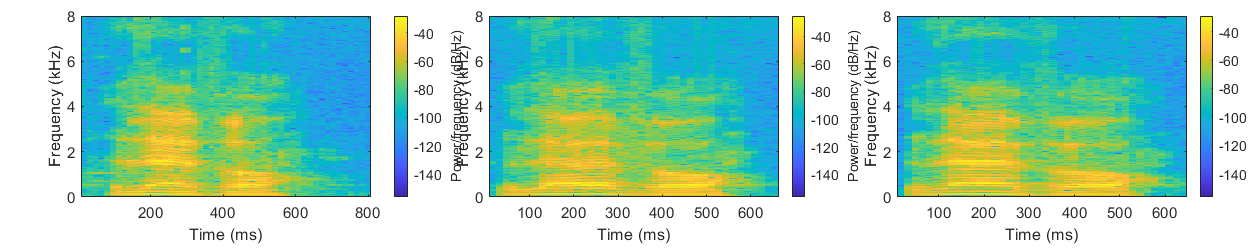

spec3(data{4}, data{5}, data{6}, 512, 256, [], fs);

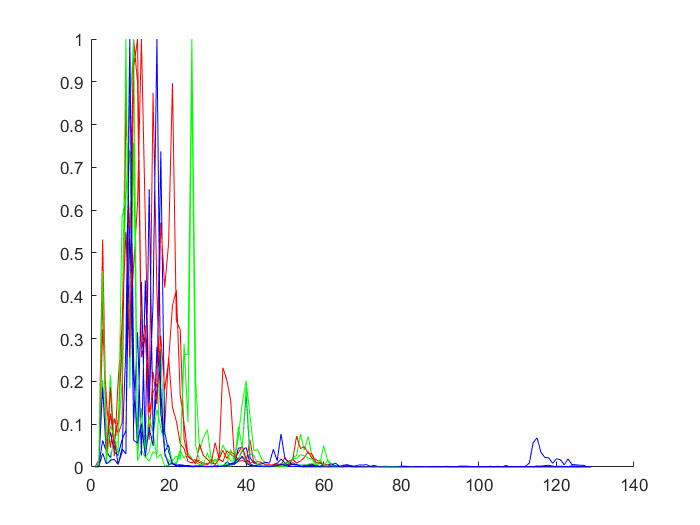

nfft = 256;
psd = zeros(nfft / 2 + 1, length(data));
for k = 1:length(data)
    psd(:,k) = pwelch(data{k}, 512, 256, nfft, fs);
    psd(:,k) = psd(:,k) / max(psd(:,k));
end

figure;
hold on;
for k = 1:3
    plot(psd(:, k), 'r-');
    plot(psd(:, k+3), 'g-');
    plot(psd(:, k+6), 'b-');
end

figure;
dm = squareform(pdist(psd', 'cosine'))

dm =          0    0.2906    0.1401    0.5414    0.2840    0.3738    0.5099    0.3708    0.5814    0.2599    0.3399    0.4019
    0.2906         0    0.1847    0.5373    0.4467    0.5112    0.4753    0.5790    0.6882    0.3553    0.5445    0.5468
    0.1401    0.1847         0    0.5495    0.3662    0.4019    0.5868    0.5418    0.7101    0.1942    0.3247    0.2846
    0.5414    0.5373    0.5495         0    0.4531    0.1156    0.4819    0.6602    0.5008    0.5359    0.4856    0.8174
    0.2840    0.4467    0.3662    0.4531         0    0.2807    0.6309    0.7770    0.7832    0.2988    0.5848    0.8291
    0.3738    0.5112    0.4019    0.1156    0.2807         0    0.4767    0.6133    0.4931    0.3021    0.3869    0.7717
    0.5099    0.4753    0.5868    0.4819    0.6309    0.4767         0    0.4846    0.1935    0.5816    0.3955    0.7824
    0.3708    0.5790    0.5418    0.6602    0.7770    0.6133    0.4846         0    0.3540    0.7156    0.4931    0.6367
    0.5814    0.6882    0.7

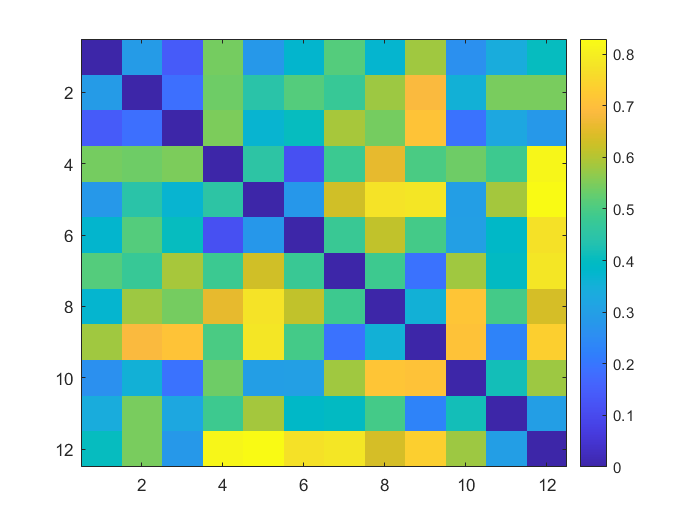

imagesc(dm);
colorbar;

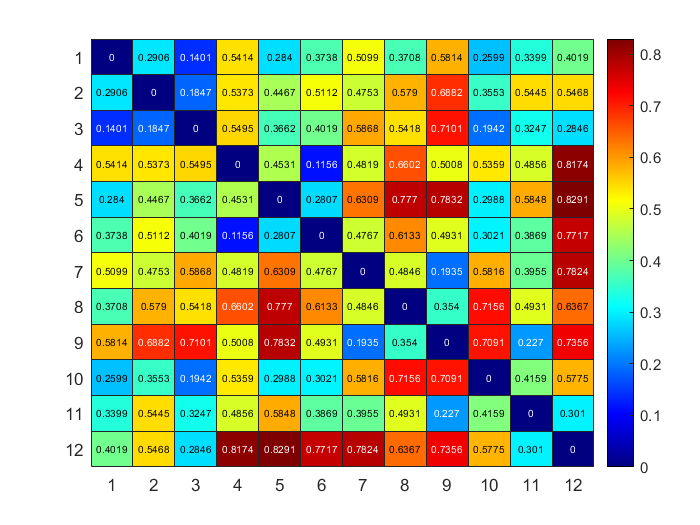

figure;
heatmap(dm);
colormap(jet(512));

dtw_dist = zeros(length(data));
for k = 1:length(data)-1
    disp(k);
    for l = k+1:length(data)
        dtw_dist(k,l) = dtw(data{k}, data{l});
        dtw_dist(l,k) = dtw_dist(k,l);
    end
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11



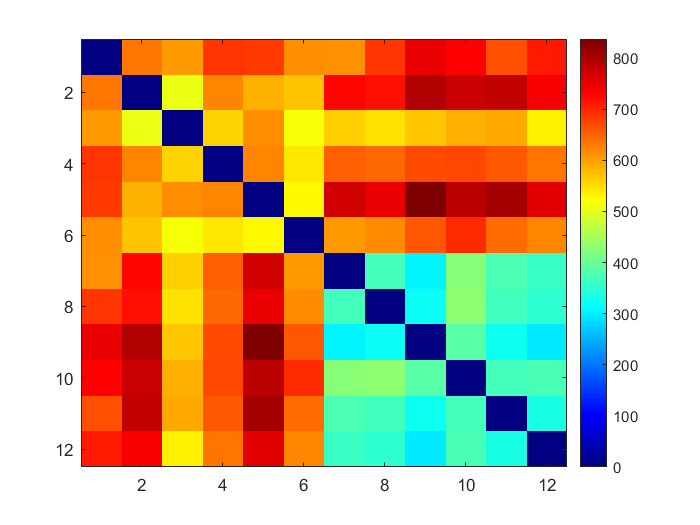

imagesc(dtw_dist);
colorbar;

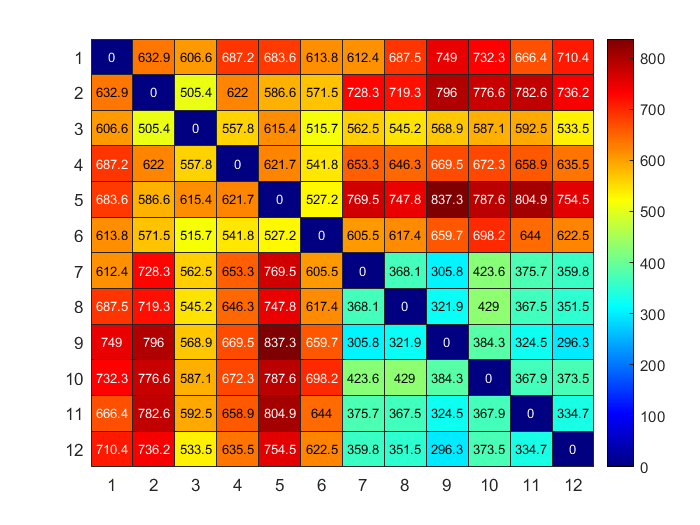

figure;
heatmap(dtw_dist);
colormap(jet(512));

function spec3(x1, x2, x3, win, overlap, nfft, fs)
    figure("Position", [0 0 1000 200]);
    tiledlayout(1,3,'Padding','Compact');
    nexttile;
    spectrogram(x1, win, overlap, nfft, fs, 'yaxis');
    nexttile;
    spectrogram(x2, win, overlap, nfft, fs, 'yaxis');
    nexttile;
    spectrogram(x3, win, overlap, nfft, fs, 'yaxis');
end


function preds = predict(data, labels, x)
% N = liczba klas
% L = liczba próbek treningowych
% greeds = 1xN
% data = 1:labels
% labels = 1xL

end